%exam 11 jan 2019

EX1

B_1

syms q1 real
syms q2 real
syms q3 real
syms q4 real

syms a4 positive real
syms d1 positive real

alpha = [pi/2, pi/2, pi/2, 0];
a=[0,0,0,a4];
d=[d1,0,q3,0];
theta=[q1,q2,pi,q4];

table=[alpha',a',d',theta'];

[T, A] = DHMatrix(table);
A0_1=A{1};
A1_2=A{2};
A2_3=A{3};
A3_4=A{4};

A0_1
A1_2
A2_3
A3_4

B_2

O4_h = [0 0 0 1]';
p4_h = T*O4_h %he said that this is not efficient

C_1

%useless unsignment, they are ignored 
q1=pi;
q2=pi;
q3=pi;
q4=pi;

%must be small value to show the robot in a good way
a4=0.4;
d1=0.4;

alpha_no_sym = [pi/2, pi/2, pi/2, 0];
a_no_sym=[0,0,0,a4];
d_no_sym=[d1,0,q3,0];
theta_no_sym=[q1,q2,pi,q4];

%Note: it has different format respect to Sveva's DHMatrix function
DHTable=[a_no_sym', alpha_no_sym',d_no_sym',theta_no_sym'];
joints = 'RRPR';
robot_model = build_robot_model(joints, DHTable);

%set to position using build_configuration
q1 = 0;
q2 = pi/2;
q3 = 0.2;   % L
q4 = 0;
array_joint_values = [q1,q2,q3,q4];
config = build_configuration(robot_model, array_joint_values);
show(robot_model, config);
%show(robot_model, randomConfiguration(robot_model));

C_2

q1=0;
q2=pi/2;
L = sym('L');
q4=0;
q3 = L;

a4=sym('a4');
d1=sym('d1');

subs(p4_h)

EX 2

A

syms q1 real
syms q2 real
syms q3 real
syms q4 real

f_r = get_f_r(T)
[Jl, Ja] = geometric_jacobian(f_r, joints, [q1 q2 q3 q4], table)
rank(Ja)
J = [Jl; Ja]

B_1

%Jacobian in configuration config_0 = (0 pi/2 L 0)'
q1 = 0;
q2=pi/2;
syms L real;
q3 = L;
q4=0;

Jl_0 = simplify(subs(Jl))
Ja_0 = simplify(subs(Ja))
J_0 = simplify(subs(J))
null_Jl_0 = null(Jl_0)
q_a_dot = null_Jl_0;
%check
v_a = Jl_0*q_a_dot

% calculate also w
w_0 = Ja_0 * q_a_dot

%indeed the null space of the overall matrix is empty
null(J_0)

## b_2

v = [1 0 1 0 0 -2]'
J_0
rank(J_0)

range_space = simplify(orth(J_0))
rank(range_space)
%check if v is feasible
A = [range_space, v]
rank(A)
%since the rank is increased, it means that v is linear independent by the
%range space of J_0, so v is not feasible!

## b_3

%   joints_torque = J' * F
F_e_null = simplify(null(J_0'))

%check
alpha_1=1
alpha_2=1
F_e_check = F_e_null(:, 1) * alpha_1 + F_e_null(:, 2) * alpha_2
joints_torque = J_0' * F_e_check

% EXERCISE 3

## RP PLANAR POS-POS ROBOT

syms q1 real
syms q2 real

% KINEMATIC
fprintf("______________________________Direct Kinematic___________________________________\n")

______________________________Direct Kinematic___________________________________


r_x = q2*cos(q1);
r_y = q2*sin(q1);

f_r = [r_x;r_y]

$$f\_r = \left(\begin{array}{c} q_{2}\,\cos\left(q_{1}\right)\\ q_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

fprintf("______________________________Inverse Kinematic___________________________________\n")

______________________________Inverse Kinematic___________________________________


syms px py

%positive solution
q1_p = atan2(py,px);
q2_p=sqrt(px^2+py^2);
q_p = [q1_p;q2_p]

$$q\_p = \left(\begin{array}{c} \text{atan2}\left(\mathrm{py},\mathrm{px}\right)\\ \sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}} \end{array}\right)$$

    
%negative solution
q1_n = atan2(-py,-px);
q2_n = -sqrt(px^2+py^2);
q_n = [q1_n;q2_n]

$$q\_n = \left(\begin{array}{c} \text{atan2}\left(-\mathrm{py},-\mathrm{px}\right)\\ -\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}} \end{array}\right)$$

% P_a
px = 4

px = 4

py = 3

py = 3


q_a = simplify(subs(q_p))

$$q\_a = \left(\begin{array}{c} \mathrm{atan}\left(\frac{3}{4}\right)\\ 5 \end{array}\right)$$

    double(q_a)

ans =     0.6435
    5.0000



% P_b
px = -3.5355

px = -3.5355

py = -px

py = 3.5355


q_b = simplify(subs(q_p))

$$q\_b = \left(\begin{array}{c} \frac{3\,\pi }{4}\\ \frac{7071\,\sqrt{2}}{2000} \end{array}\right)$$

    double(q_b)

ans =     2.3562
    5.0000


syms t real
syms A1 real
syms T real


% Acceleration
A1_t_1 = A1

$$A1\_t\_1 = A_{1}$$

A1_t_2 = -A1

$$A1\_t\_2 = -A_{1}$$


% Velocity
V1_t_1 = A1*t

$$V1\_t\_1 = A_{1}\,t$$

V1_t_2 = -A1*t+A1*T

$$V1\_t\_2 = A_{1}\,T-A_{1}\,t$$

V1_t_max = subs(V1_t_1, {t},{T/2})

$$V1\_t\_max = \frac{A_{1}\,T}{2}$$


% Position
P1_t_1 = q_a(1) +(A1*t^2)/2

$$P1\_t\_1 = \frac{A_{1}\,t^{2}}{2}+\mathrm{atan}\left(\frac{3}{4}\right)$$

P1_t_2 = q_a(1) +(A1*(T/2)^2)/2 - (A1*t^2)/2 + A1*T*t + (A1*(T/2)^2)/2 - A1*T*(T/2) 

$$P1\_t\_2 = -\frac{A_{1}\,T^{2}}{4}+A_{1}\,T\,t-\frac{A_{1}\,t^{2}}{2}+\mathrm{atan}\left(\frac{3}{4}\right)$$


P1_t_2_T = subs(P1_t_2, {t}, {T})

$$P1\_t\_2\_T = \frac{A_{1}\,T^{2}}{4}+\mathrm{atan}\left(\frac{3}{4}\right)$$


eq = P1_t_2_T == q_b(1)

$$eq = \frac{A_{1}\,T^{2}}{4}+\mathrm{atan}\left(\frac{3}{4}\right)=\frac{3\,\pi }{4}$$

T = solve(eq, T ,'ReturnConditions',true)

T = struct with fields:
             T: [2×1 sym]
    parameters: [1×0 sym]
    conditions: [2×1 sym]


T.T

$$ans = \left(\begin{array}{c} \frac{\sqrt{3\,\pi -4\,\mathrm{atan}\left(\frac{3}{4}\right)}}{\sqrt{A_{1}}}\\ -\frac{\sqrt{3\,\pi -4\,\mathrm{atan}\left(\frac{3}{4}\right)}}{\sqrt{A_{1}}} \end{array}\right)$$

T.conditions

$$ans = \left(\begin{array}{c} 0<A_{1}\\ 0<A_{1} \end{array}\right)$$

T.parameters

 
ans =
 
Empty sym: 1-by-0
 



A1 = deg2rad(200);
%so, the solution for T is:
T_syms = T.T(1);
T = simplify(subs(T_syms))

$$T = \frac{3\,\sqrt{10}\,\sqrt{2\,\pi +\mathrm{atan}\left(\frac{336}{527}\right)}}{10\,\sqrt{\pi }}$$

T = double(T)

T = 1.4009


% Acceleration
A1_t_1 = subs(A1_t_1)

$$A1\_t\_1 = \frac{10\,\pi }{9}$$

A1_t_2 = subs(A1_t_2)

$$A1\_t\_2 = -\frac{10\,\pi }{9}$$

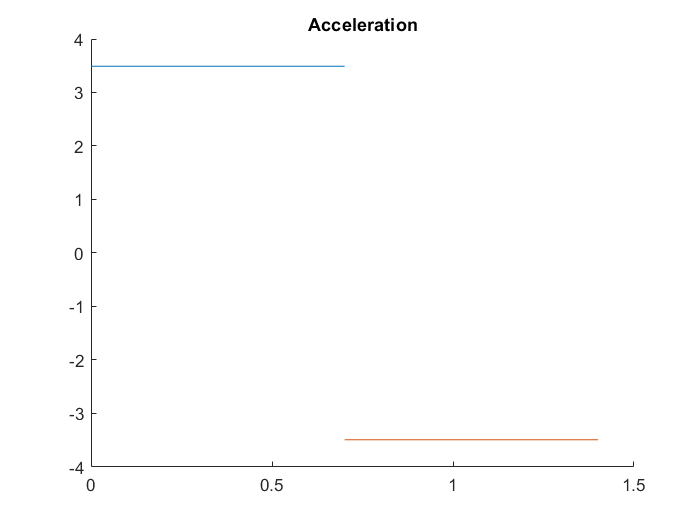


clf
hold on 
title("Acceleration")
fplot(A1_t_1, [0 T/2])
fplot(A1_t_2, [T/2, T])
hold off


% Velocity
V1_t_1 = subs(V1_t_1)

$$V1\_t\_1 = \frac{10\,\pi \,t}{9}$$

V1_t_2 = subs(V1_t_2)

$$V1\_t\_2 = \frac{15773058241806085\,\pi }{10133099161583616}-\frac{10\,\pi \,t}{9}$$

V1_t_max = subs(V1_t_max)

$$V1\_t\_max = \frac{15773058241806085\,\pi }{20266198323167232}$$

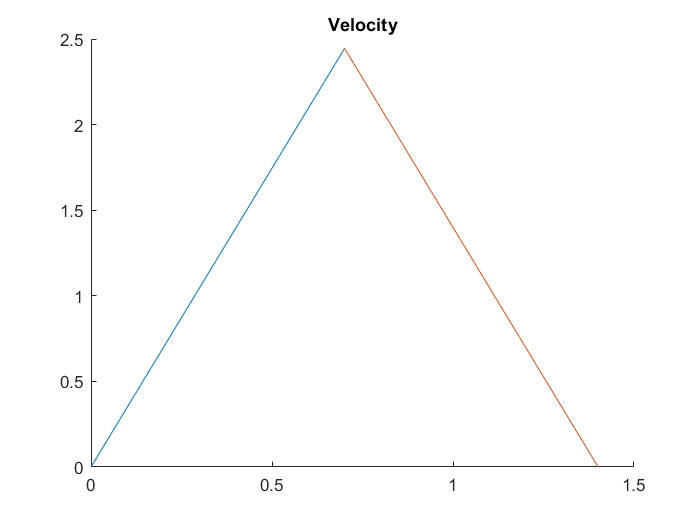


clf
hold on 
title("Velocity")
fplot(V1_t_1, [0 T/2])
fplot(V1_t_2, [T/2, T])
hold off


% Position JOINT Q1
P1_t_1 = subs(P1_t_1)

$$P1\_t\_1 = \frac{5\,\pi \,t^{2}}{9}+\mathrm{atan}\left(\frac{3}{4}\right)$$

P1_t_2 = subs(P1_t_2)

$$P1\_t\_2 = -\frac{5\,\pi \,t^{2}}{9}+\frac{15773058241806085\,\pi \,t}{10133099161583616}-\frac{49757873259881373077208548605445\,\pi }{91270843216432516907762630787072}+\mathrm{atan}\left(\frac{3}{4}\right)$$

q1_05T = subs(P1_t_1, {t}, {T/2})

$$q1\_05T = \frac{49757873259881373077208548605445\,\pi }{182541686432865033815525261574144}+\mathrm{atan}\left(\frac{3}{4}\right)$$

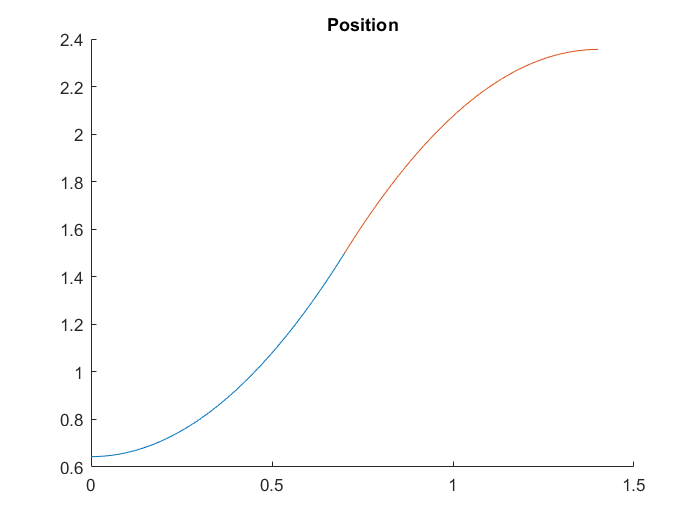

clf
hold on 
title("Position")
fplot(P1_t_1, [0 T/2])
fplot(P1_t_2, [T/2, T])
hold off

% EXERCISE 3.b

f_r

$$f\_r = \left(\begin{array}{c} q_{2}\,\cos\left(q_{1}\right)\\ q_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

syms q1 real
syms q2 real
J = jacobian(f_r, [q1 q2])

$$J = \left(\begin{array}{cc} -q_{2}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\\ q_{2}\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right) \end{array}\right)$$


syms q1(t) q2(t);
q1 = q1(t);
q2 = q2(t);

J_t = subs(J)

$$J\_t = \left(\begin{array}{cc} -\sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) & \cos\left(q_{1}\left(t\right)\right)\\ \cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) & \sin\left(q_{1}\left(t\right)\right) \end{array}\right)$$

J_dot = diff(J_t,t)

$$J\_dot = \left(\begin{array}{cc} -\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-\cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) & -\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ \cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-\sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) & \cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) \end{array}\right)$$


q1_dot = diff(q1, t);
q2_dot = diff(q2, t);

q1_dot_dot = diff(q1_dot, t);
q2_dot_dot = diff(q2_dot, t);

q = [q1;q2];
q_dot = [q1_dot; q2_dot];
q_dot_dot = [q1_dot_dot; q2_dot_dot];

r_dot = J*q_dot

$$r\_dot = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-q_{2}\,\sin\left(q_{1}\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ \sin\left(q_{1}\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)+q_{2}\,\cos\left(q_{1}\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) \end{array}\right)$$

r_dot_dot = J*q_dot_dot + J_dot * q_dot

$$r\_dot\_dot = \begin{array}{l} \left(\begin{array}{c} \cos\left(q_{1}\right)\,\sigma_{1}-\left(\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)+\cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)-\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)-q_{2}\,\sin\left(q_{1}\right)\,\sigma_{2}\\ \left(\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-\sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+\sin\left(q_{1}\right)\,\sigma_{1}+\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+q_{2}\,\cos\left(q_{1}\right)\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right) \end{array}$$

% calculate r_dot_dot in the max acceleration
r_dot_dot_max = simplify(subs(r_dot_dot, {q1_dot_dot, q2_dot_dot}, {A1,0}))

$$r\_dot\_dot\_max = \begin{array}{l} \left(\begin{array}{c} -\cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\sigma_{1}-2\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)-\frac{10\,\pi \,q_{2}\,\sin\left(q_{1}\right)}{9}\\ -\sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\sigma_{1}+2\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{10\,\pi \,q_{2}\,\cos\left(q_{1}\right)}{9} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2} \end{array}$$

r_dot_dot_max = simplify(subs(r_dot_dot_max, {q1_dot, q2_dot}, {V1_t_max,0}))

$$r\_dot\_dot\_max = \left(\begin{array}{c} -\frac{10\,\pi \,q_{2}\,\sin\left(q_{1}\right)}{9}-\frac{248789366299406865386042743027225\,\pi^{2}\,\cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)}{410718794473946326084931838541824}\\ \frac{10\,\pi \,q_{2}\,\cos\left(q_{1}\right)}{9}-\frac{248789366299406865386042743027225\,\pi^{2}\,\sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)}{410718794473946326084931838541824} \end{array}\right)$$

r_dot_dot_max = simplify(subs(r_dot_dot_max, {q1, q2}, {q1_05T,5}))

$$r\_dot\_dot\_max = \left(\begin{array}{c} -\frac{1243946831497034326930213715136125\,\pi^{2}\,\cos\left(\frac{49757873259881373077208548605445\,\pi }{182541686432865033815525261574144}+\mathrm{atan}\left(\frac{3}{4}\right)\right)}{410718794473946326084931838541824}-\frac{10\,\pi \,q_{2}\,\sin\left(q_{1}\right)}{9}\\ \frac{10\,\pi \,q_{2}\,\cos\left(q_{1}\right)}{9}-\frac{1243946831497034326930213715136125\,\pi^{2}\,\sin\left(\frac{49757873259881373077208548605445\,\pi }{182541686432865033815525261574144}+\mathrm{atan}\left(\frac{3}{4}\right)\right)}{410718794473946326084931838541824} \end{array}\right)$$

double(r_dot_dot_max)

Error using symengine
Unable to convert expression containing symbolic variables into double array. Apply 'subs' function first to substitute values for variables.

Error in sym/double (line 702)
        Xstr = mupadmex('symobj::double', S.s, 0);